# Analysis

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_Three_Pipes
r_sensor=2 mm
Q_inlet_CNN=5 uL/min
height_pipe=36 um
c_Tartrazine_exp=0.08455 mol/L


c_max = 1

c_inlet=0.001 mol/L


mu = 9.9792e-04

D_coeff=4.9e-10 m^2/s


time_delta = 0.5000

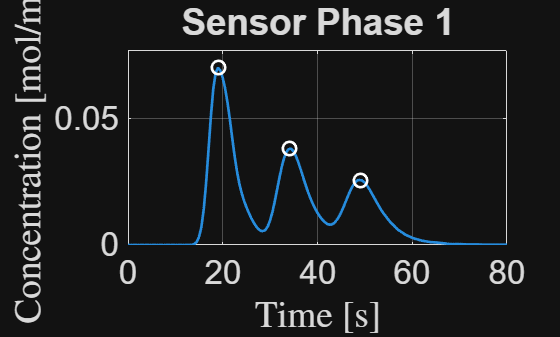

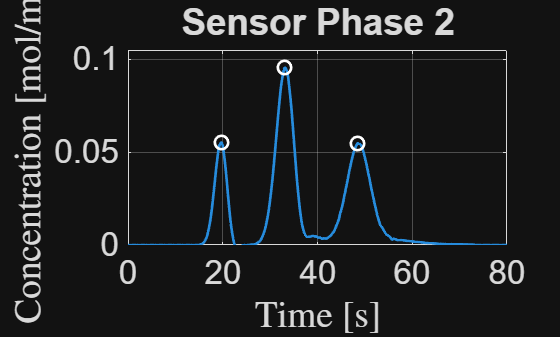

Analysis_Phase_2

#### Phase 3: Load

% Specify the CSV file
csvFileName = 'c_CNN_Phase_3.csv';
% Var 2- > alpha_outlet=0.65; time_delta=0.5
% Var 3- > alpha_outlet=0.7; time_delta=0.5
% Var 4- > alpha_outlet=0.65; time_delta=0.5
% Var 5- > alpha_outlet=0.64; time_delta=0.5
% Var 5- > alpha_outlet=0.65; time_delta=0.5


csvFileName = 'c_CNN_Phase_3.csv';
% Var 2- > alpha_outlet=0.65; time_delta=0.01

%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
Table_c_Pipe_CNN=readtable(csvFileName,opts);
t_COMSOL_Phase_3=(Table_c_Pipe_CNN.Var1);
dt=t_COMSOL_Phase_3(2)-t_COMSOL_Phase_3(1);
c_COMSOL_CNN_Phase_3=(Table_c_Pipe_CNN.Var2);
h_COMSOL_CNN_Phase_3=gradient(c_COMSOL_CNN_Phase_3,t_COMSOL_Phase_3);

%finding the peaks
%First peak
x1=1;
x2=x1+round(1/4*length(h_COMSOL_CNN_Phase_3));
[~,t_peak_A_COMSOL_Phase_3]=max(h_COMSOL_CNN_Phase_3(x1:x2));

%Second peak
x1=x2;
x2=x1+(tau_sample)/dt;
[~,t_peak_B_COMSOL_Phase_3]=max(h_COMSOL_CNN_Phase_3(x1:x2));
t_peak_B_COMSOL_Phase_3=t_peak_B_COMSOL_Phase_3+x1-1;

%Third peak
x1=x2;
[~,t_peak_C_COMSOL_Phase_3]=max(h_COMSOL_CNN_Phase_3(x1:end));
t_peak_C_COMSOL_Phase_3=t_peak_C_COMSOL_Phase_3+x1-2;
% t_peak_C_COMSOL=(t_peak_C_COMSOL-1)*time_delta+(x1-1)*time_delta;

disp(['Sampling time'])

Sampling time


(t_peak_B_COMSOL_Phase_3-1)*dt-(t_peak_A_COMSOL_Phase_3-1)*dt

ans = 15.5500

disp(['Sampling time'])

Sampling time


(t_peak_C_COMSOL_Phase_3-1)*dt-(t_peak_B_COMSOL_Phase_3-1)*dt

ans = 15.4200

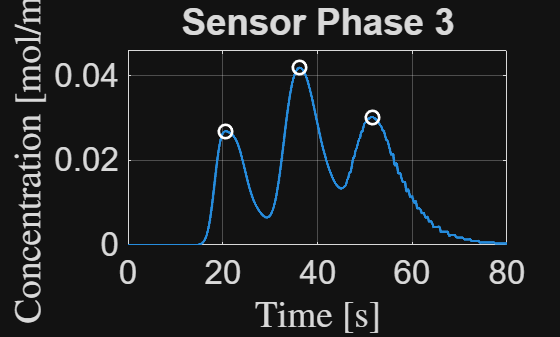


figure;

% % plot(time,h_cir_1_Theo,'LineWidth',2); grid on; hold on;
plot(t_COMSOL_Phase_3,h_COMSOL_CNN_Phase_3,'LineWidth',2); grid on; hold on;
plot((t_peak_A_COMSOL_Phase_3-1)*dt,h_COMSOL_CNN_Phase_3((t_peak_A_COMSOL_Phase_3)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;
plot((t_peak_B_COMSOL_Phase_3-1)*dt,h_COMSOL_CNN_Phase_3((t_peak_B_COMSOL_Phase_3)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;
plot((t_peak_C_COMSOL_Phase_3)*dt,h_COMSOL_CNN_Phase_3((t_peak_C_COMSOL_Phase_3)),'ow','LineWidth',2,'MarkerSize',10); grid on; hold on;% plot([x1 x1]*time_delta,[0 1])
% plot([x1 x1]*time_delta,[0 1])
% plot([x2 x2]*time_delta,[0 1])

xlabel('Time [s]','Interpreter','latex');
ylabel('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
title('Sensor Phase 3')
axis([0 t(end) 0 1.1*max(h_COMSOL_CNN_Phase_3)]);